# First order approximation demo

**Disclaimer:** This demo does contain a political opinion to favour renewables due to the global warming.

Let us assume a second order system, that we will in this document approximate as a first order system. Let us compose a second order system as a sum of two simple first order systems:


$$G_o = \frac{1}{s-p_1} + \frac{1}{s-p_2}$$


Note that we are here expressing the denominators as $s - p_n$ and not with a $+$ since we want the values of $p_n$ to directly tell the location of the pole $s-p_n=0$ $\Rightarrow s= p_n$.

By simple calculus, we can modify the sum of these simple first order systems to a form that we are more familiar with when talking about a second order system:


$$G_o = \frac{s-p_2 + s-p_1}{(s-p_1)(s-p_2)}$$


And finally we have the second order system transfer function as:


$$G_o = \frac{2s - p_1 - p_2}{(s-p_1)(s-p_2)}$$


In order to approximate this system as a first order system, there are few important questions that need to be answered:

- When is the approximation 'good', when it makes sense?

- Which pole to choose for the approximation?

In order to answer these questions, we need to take a look into how **dominant poles** work.

### How the dominant poles affect the system response and evolution over time.

**Task 1:**

**Change the pole values here and observe what happens to the average distance from the true signal (RMSE). The smaller the RMSE, the closer it is to the real output, with 0 meaning identical.**

- Place the poles very close to each other on the left half plane

- Start to move one pole further away on the left half plane

- You can even try two unstable poles, try p1 = 10, p2 = 0.1 and end_time = 10. See how the maximal pole is the dominant one, even when the system is unstable. The figure might be a bit hard to read with these but you can confirm from the RMSE value.

% NOTICE: change the pole values!
p1 = -2;
p2 = -15;

% you can also change the end time if you like
end_time = 1;

In order to look how the produced signal of the system works when we just allow it to evolve naturally, we need to take the inverse Laplace transforms:


$$L\left\{ \frac{1}{s-p_n} \right\}^{-1} = e^{p_n t}$$



$$L\left\{G_1 + G_2 \right\}^{-1} = L\left\{G_1 \right\}^{-1} + L\left\{G_1\right\}^{-1}$$


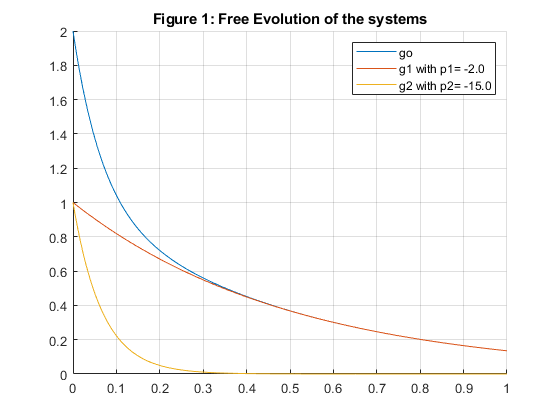

t = linspace(0,end_time,1000);

g1 = exp(p1*t);
g2 = exp(p2*t);
go = g1 + g2;

text1 = sprintf("g1 with p1= %.1f", p1);
text2 = sprintf("g2 with p2= %.1f", p2);

figure;
hold on
grid on
plot(t, go);
plot(t, g1);
plot(t, g2);
legend('go', text1, text2)
title('Figure 1: Free Evolution of the systems')

Furthermore, we can observe how distant the approximations are from the true signal. RMSE is the root of the mean squared error, in other words, how distant the signal is on average from the original one.

rmseO1 = sqrt(mean((go-g1).^2))

rmseO1 = 0.1839

rmseO2 = sqrt(mean((go-g2).^2))

rmseO2 = 0.4957

In addition, we can also take a look at the step response of the system and the approximations.

**Task 2:**

**Change the pole values and observe, how the dominant pole approximation becomes better and better the further away the poles are from each other.**

- Hint: hold the value of p1 = -5 and change p2 = -5, p2 = -10, p2 = -50, p2 = -100 and p2 = -500.

- You can then try to increase the value of p1 closer to p2 and also observe how the approximation starts to become worse again.

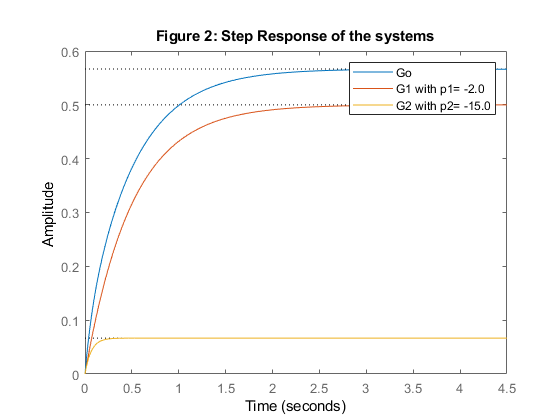

s = tf('s');
Go = (2*s-p1-p2)/((s-p1)*(s-p2));
G1 = 1/(s-p1);
G2 = 1/(s-p2);

text1 = sprintf("G1 with p1= %.1f", p1);
text2 = sprintf("G2 with p2= %.1f", p2);

figure;
hold on
grid on
step(Go);
step(G1);
step(G2);
legend('Go', text1, text2)
title('Figure 2: Step Response of the systems')

## Conclusion

Even though this was an approximation from a second order system to the first order system, the same principles apply to higher degrees. Approximating a higher order system as a lower order system makes sense when the dominant poles are far from the rest. The approximation can always be done, but the quality of the approximation gets better as the distance between the dominant poles and the non-dominant poles increases. The dominating poles, that should also be selected for the approximation, are the N maximal poles of the system, regardless if it is stabile or not, where N is the degree of your approximation.

In **stable systems**, the faster non-dominant poles only add some details to the response or signal, for which the overall shape is determined by the dominant poles (see for yourself with Task 1). Think of it as if you have the yearly temperature:

A dominant slow pole would be the average temperature of each month, say a value that slowly changes from -15 to +25 degrees of celcius. During the Winter period we have low temperatures and during the Summer period we have high temperatures. Then a faster pole that would be the temperature change during each day, at night it usually gets a bit colder and during the day the sun will often warm up the day a bit, but the temperature change within a day is just some minor detail in the overall temperature change during the year, something like -5 to +5 degrees to the monthly average. The effect of the sun during the day at Winter will not push us to the +30 degrees of celcius that we encounter during the Summer.

We could then state that if we want to observe the yearly temperature change, it is sufficient to approximate the system by only the monthly averages (slow, dominant pole) and discard the faster daily change, or, if we would like to alter the yearly temperature, we only really need to modify the dominant pole, the monthly averages, and leave the daily change untouched since it is a bit harder to change the daily sun cycle of Earth.

So please, do favour renewables, let's not change the Poles of Earth. All puns intended.